%%%%%%%%% SCANDI Wind fields explorations %%%%%%%%%%%

%%% importing data for 12.0856
winds = readtable("WNM14C21_windfit.xlsx","Sheet","example data at 12.0856 UT");

zonal = winds.zonalWindComponent_m_s_;
merid = winds.meridionalWindComponent_m_s_;
dz = winds.zonalDistances_km_;
dm = winds.meridionalDistances_km_;
angle = winds.adjustSectorAngleToBeContinuousForPlotting;

%%% positions of wind vectors

figure;
scatter(dz,dm)
title("example data at 12.0856 UT")


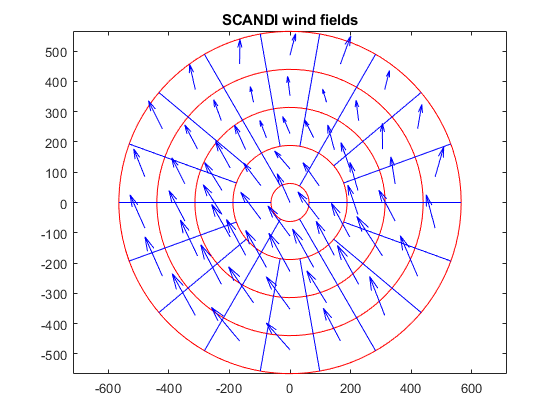

%%% plotting windfields with scandi zones

r = [62.82272976
188.4681893
314.1136488
439.7591083
565.4045678
];

fpi_loc = [16.0,78.1];
Scandi_zones([0,0],r)
hold on
quiver(dz/1000,dm/1000,zonal,merid,"b")
hold off
title("SCANDI wind fields")

%%% importing the sheet that contains all the data from the complete sheet

windfit = readtable("WNM14C21_windfit.xlsx",'Sheet', "WNM14C21_windfit");


% taking the first row of data (12.0856 UT)

for n = 1:10:(height(windfit))
    if n+3 > height(windfit)
        break
    end
    U = table2array(windfit(n+3,2:end))';
    V = table2array(windfit(n+4,2:end))';
    Scandi_zones([0,0],r);
    hold on
    quiver(dz/1000,dm/1000,U,V,"b");
    hold off
    title(windfit(n+1,:).Var2+" UT")
    
end


disp("-------------------------------------------------")

%%% creating an animated plot 

v = VideoWriter("SCANDI_movie","MPEG-4")
v.FrameRate = 4;
open(v)
for n = 1:10:height(windfit)
    if n+3 > height(windfit)
        break
    end
    U = table2array(windfit(n+3,2:end))';
    V = table2array(windfit(n+4,2:end))';
    Scandi_zones([0,0],r);
    hold on
    quiver(dz/1000,dm/1000,U,V,"b");
    xlim([-700 700]);
    ylim([-600 600]);
    title(windfit(n+1,:).Var2+" UT");
    frame = getframe(gcf);
    writeVideo(v,frame);
    
end

close(v);
hold off;

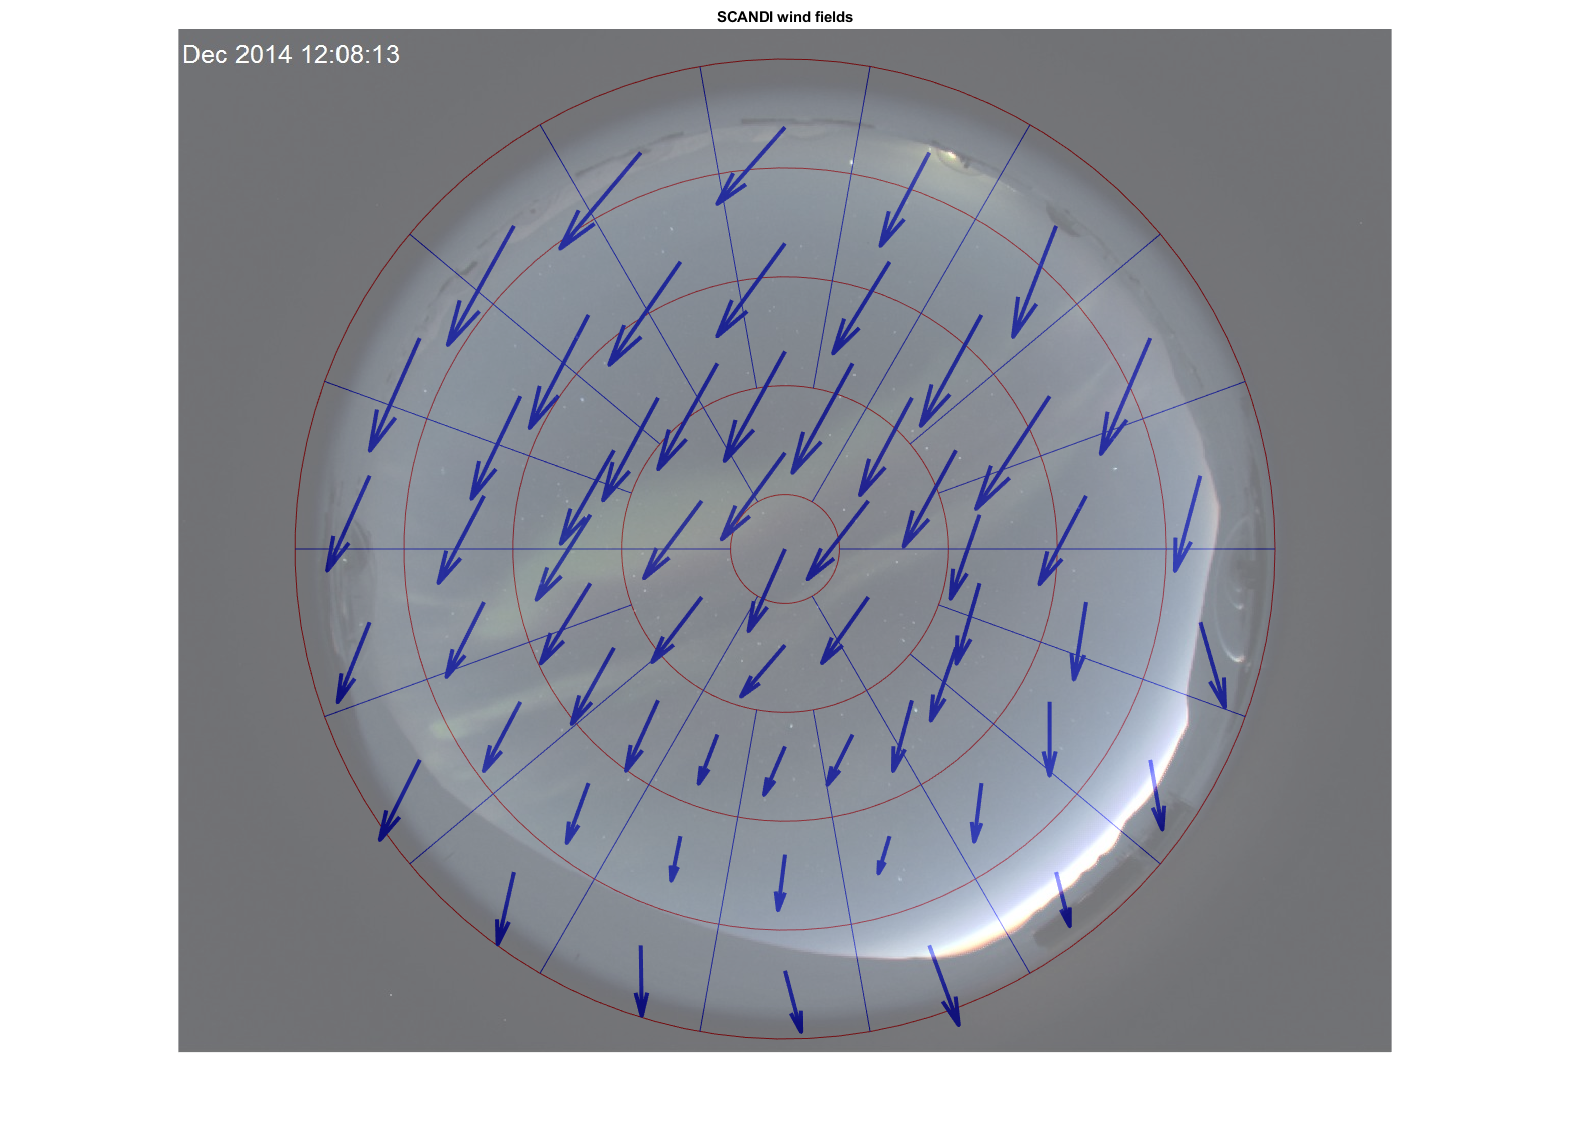

%%% Overlaying scandi first sky picture using imshow

Scandi_zones([0,0],r);
hold on
quiver(dz/1000,dm/1000,zonal,merid,"b","LineWidth",3);
hold on
title("SCANDI wind fields");
xlim([-700 700]);
ylim([-600 600]);
h = imshow("KHO_21-22Dec2014-ASC\KHO_21Dec14_12.08.13.jpg","XData", [-840 800], "YData", [-610 580]);
h.AlphaData = 0.6;
axis off
hold off

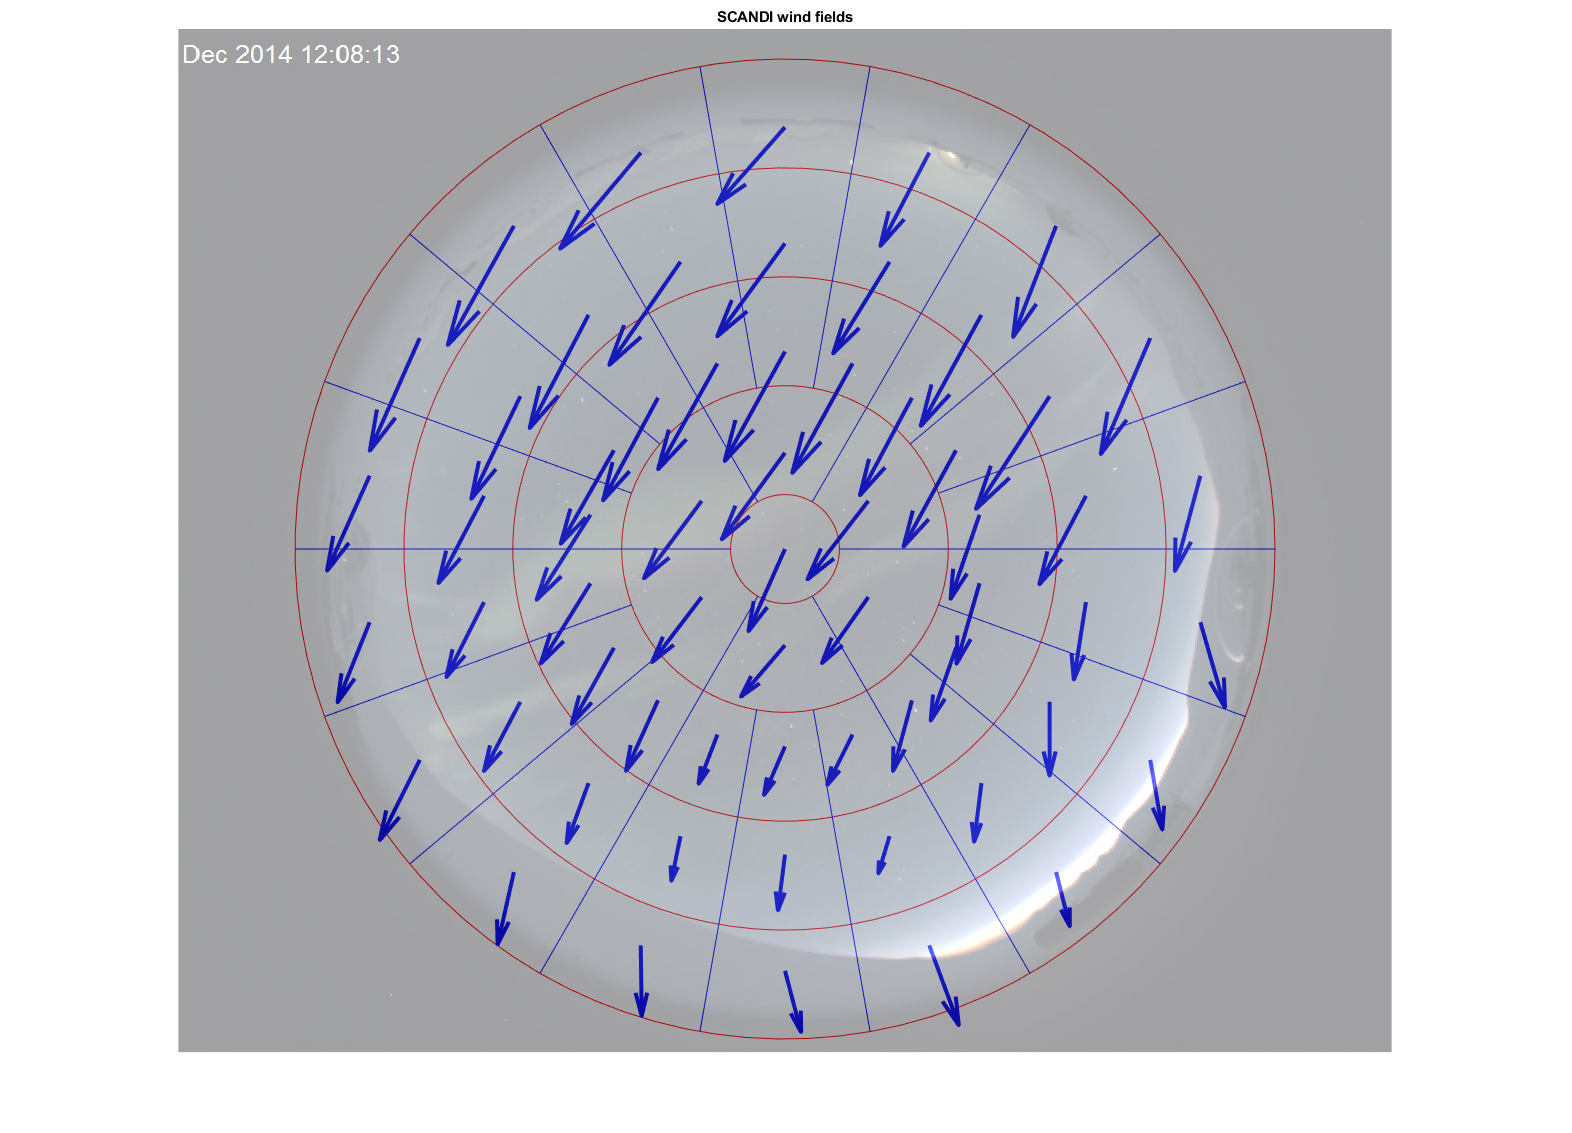

figure;
Scandi_zones([0,0],r);
hold on
quiver(dz/1000,dm/1000,zonal,merid,"b","LineWidth",3);
hold on
title("SCANDI wind fields");
xlim([-700 700]);
ylim([-600 600]);
files = dir('KHO_21-22Dec2014-ASC\*.jpg') ;
t = 12.08;
for k = 1:length(files)
    chr = files(k).name;
    if contains(chr,string(t)) == 1
    h = imshow("KHO_21-22Dec2014-ASC\"+chr,"XData", [-840 800], "YData", [-610 580]);
    h.AlphaData = 0.4;
    end
end
hold off
axis off

%% character and string manipulation

t = duration(hours(12.0857),"Format","hh:mm")

t = duration
   12:05


strrep(string(t),':','.')

ans = "12.05"

char(strrep(string(t),':','.'))

ans = '12.05'

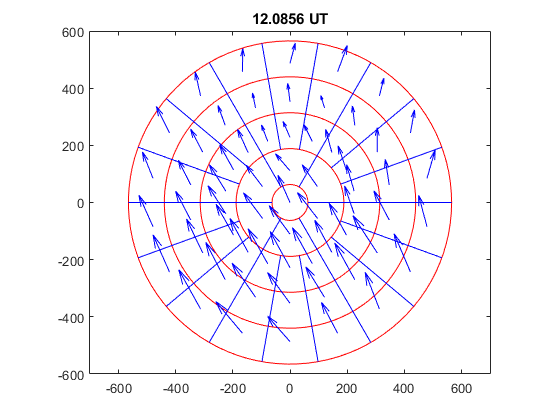

for n = 1:10:20
%     if n+3 > height(windfit)
%         break
%     end
    U = table2array(windfit(n+3,2:end))';
    V = table2array(windfit(n+4,2:end))';
    Scandi_zones([0,0],r);
    hold on
    quiver(dz/1000,dm/1000,U,V,"b");
    hold on
    xlim([-700 700])
    ylim([-600 600])
    t = windfit(n+1,:).Var2;
    title(windfit(n+1,:).Var2+" UT")
    files = dir('KHO_21-22Dec2014-ASC\*.jpg') ;
    for k = 1:length(files)
        chr = files(k).name;
        if contains(chr,string(t)) == 1
            h = imshow("KHO_21-22Dec2014-ASC\"+chr,"XData", [-840 800], "YData", [-610 580]);
            h.AlphaData = 0.4;
        end
    end
    
end

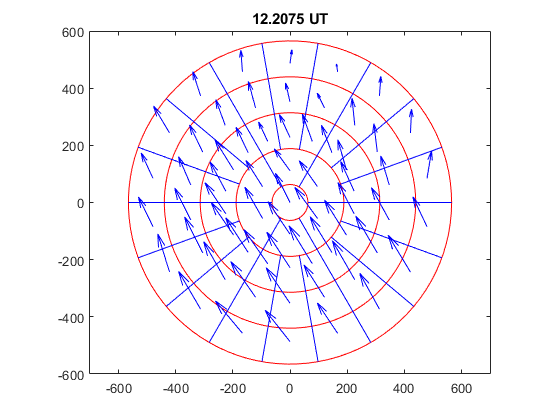

axis on
hold off